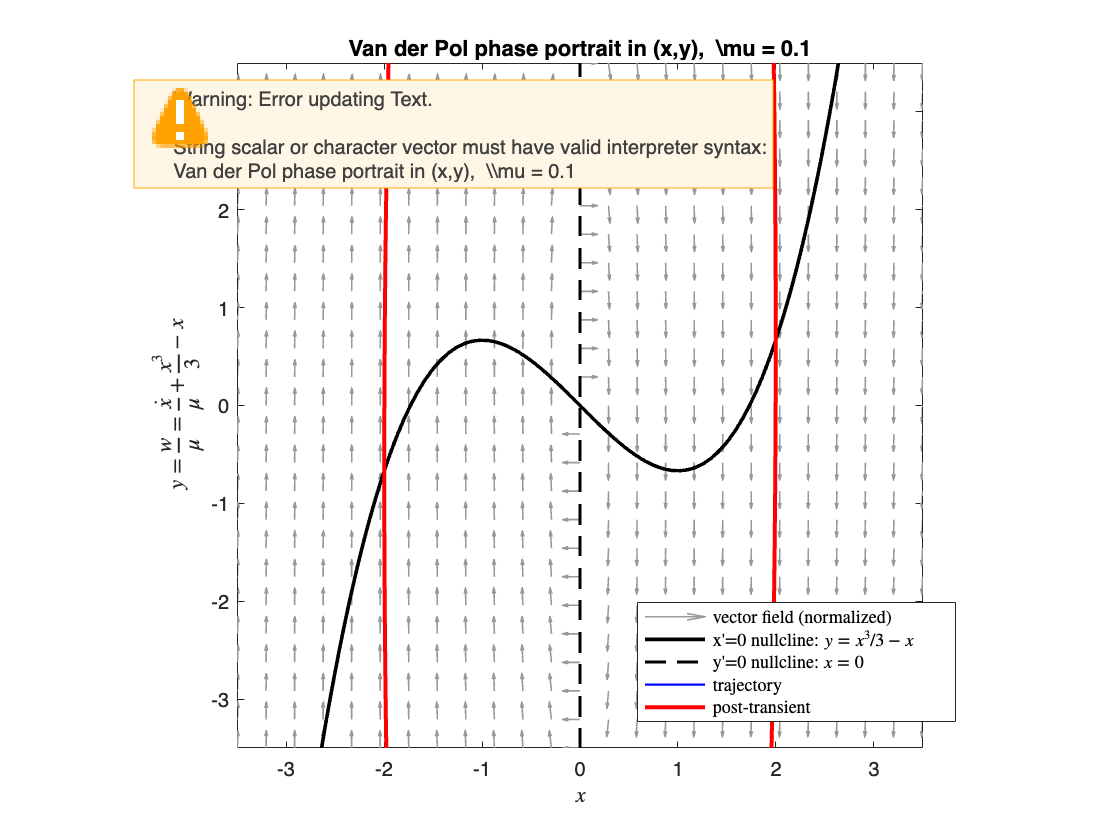

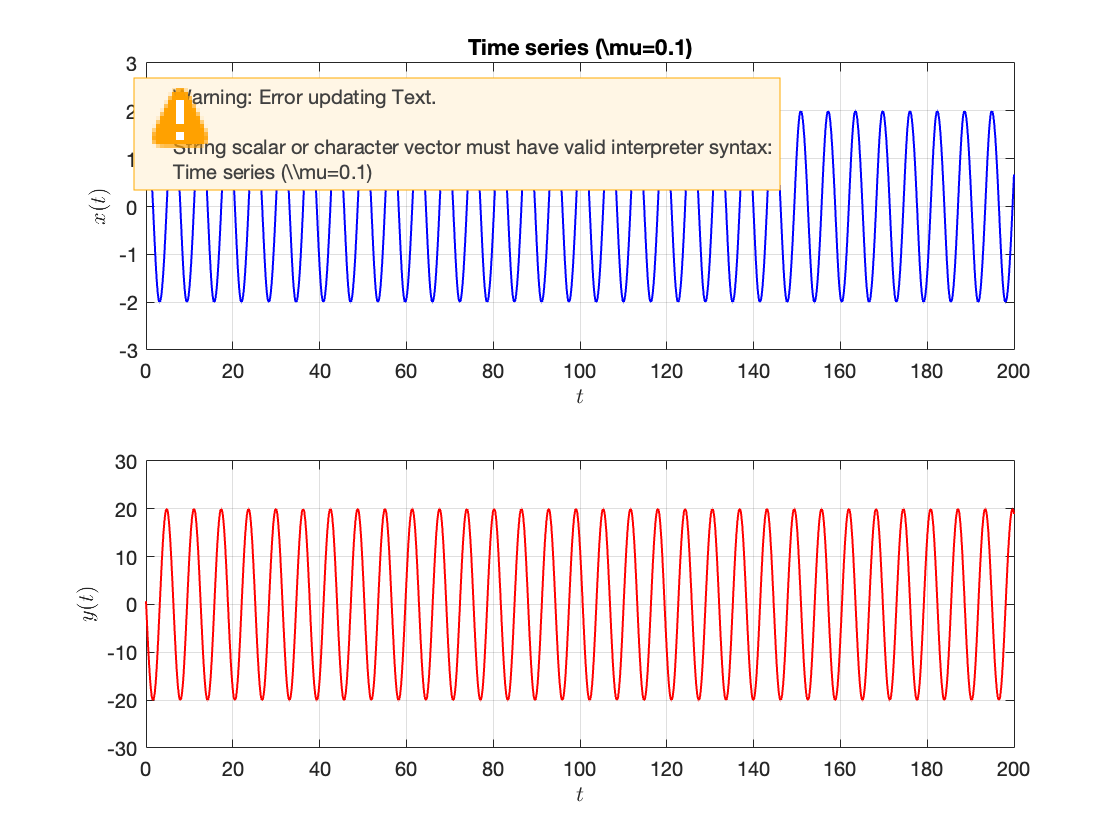

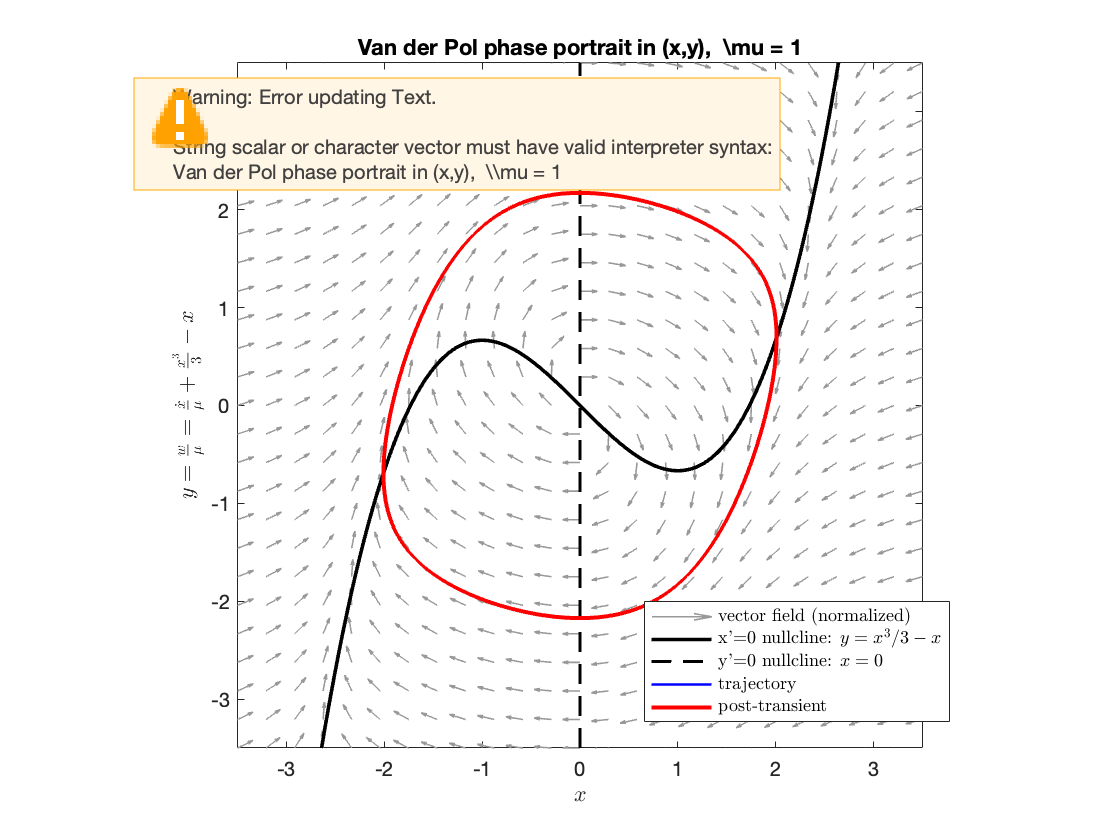

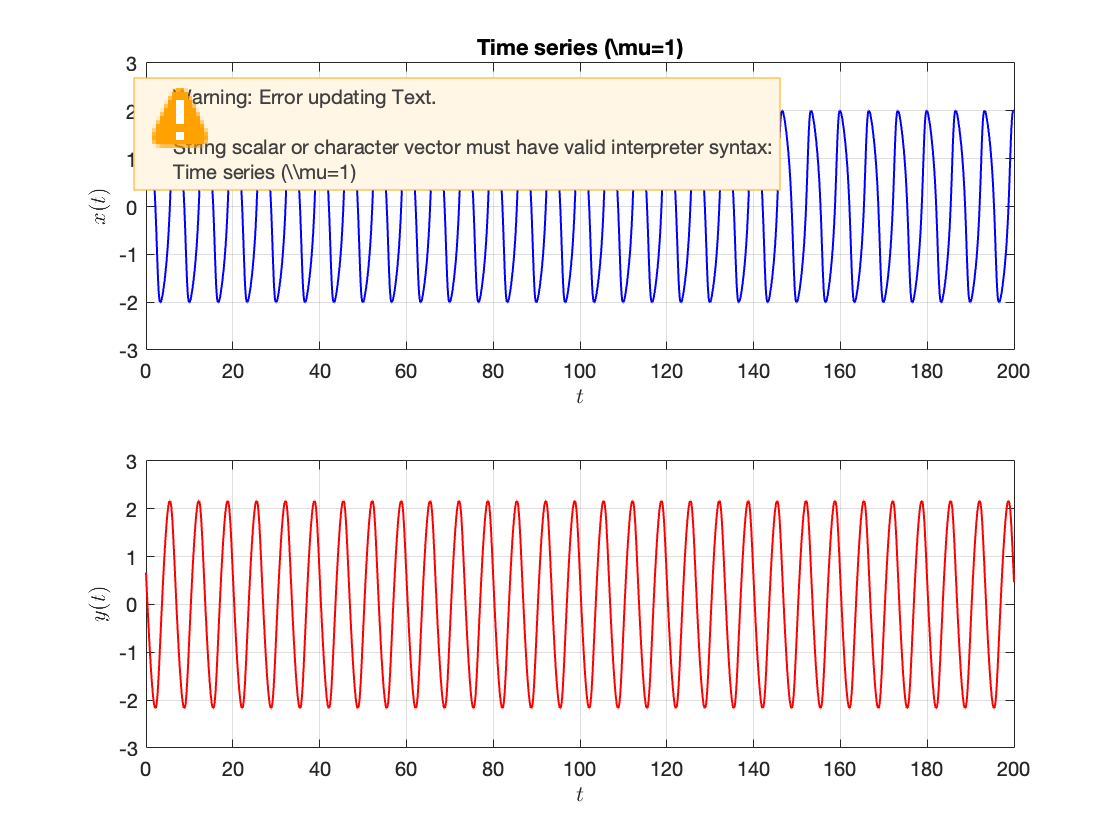

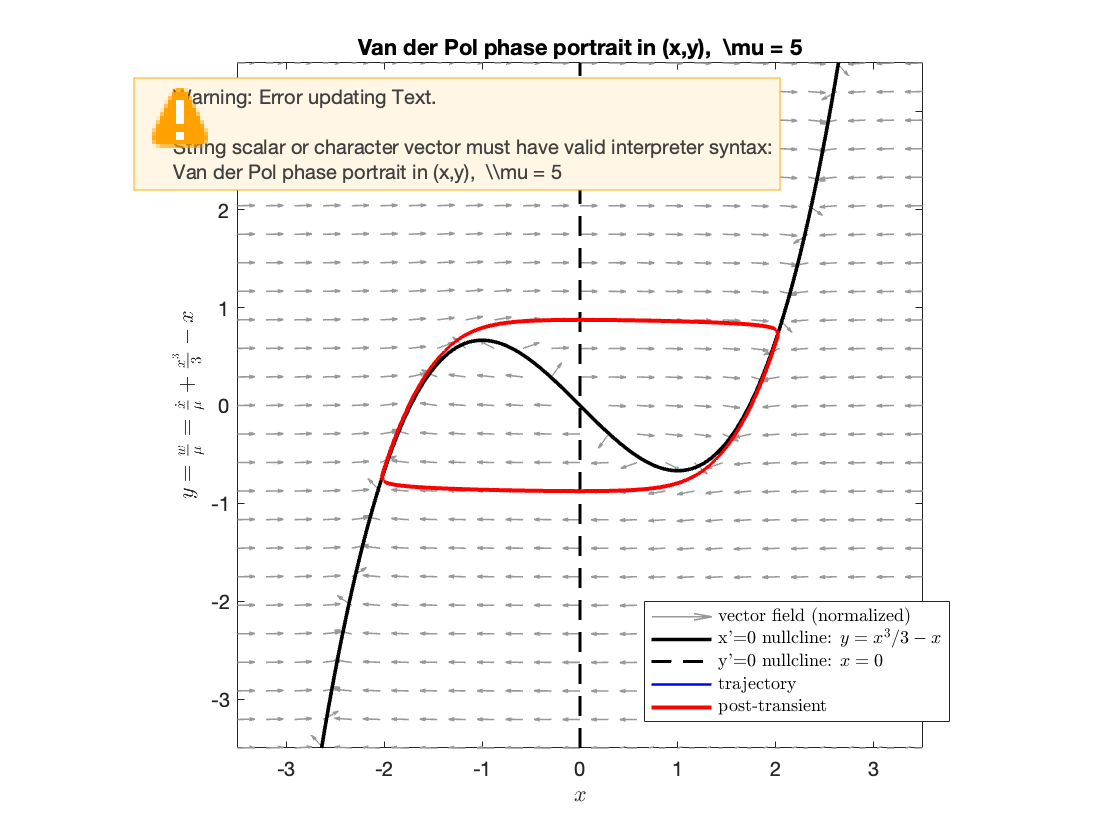

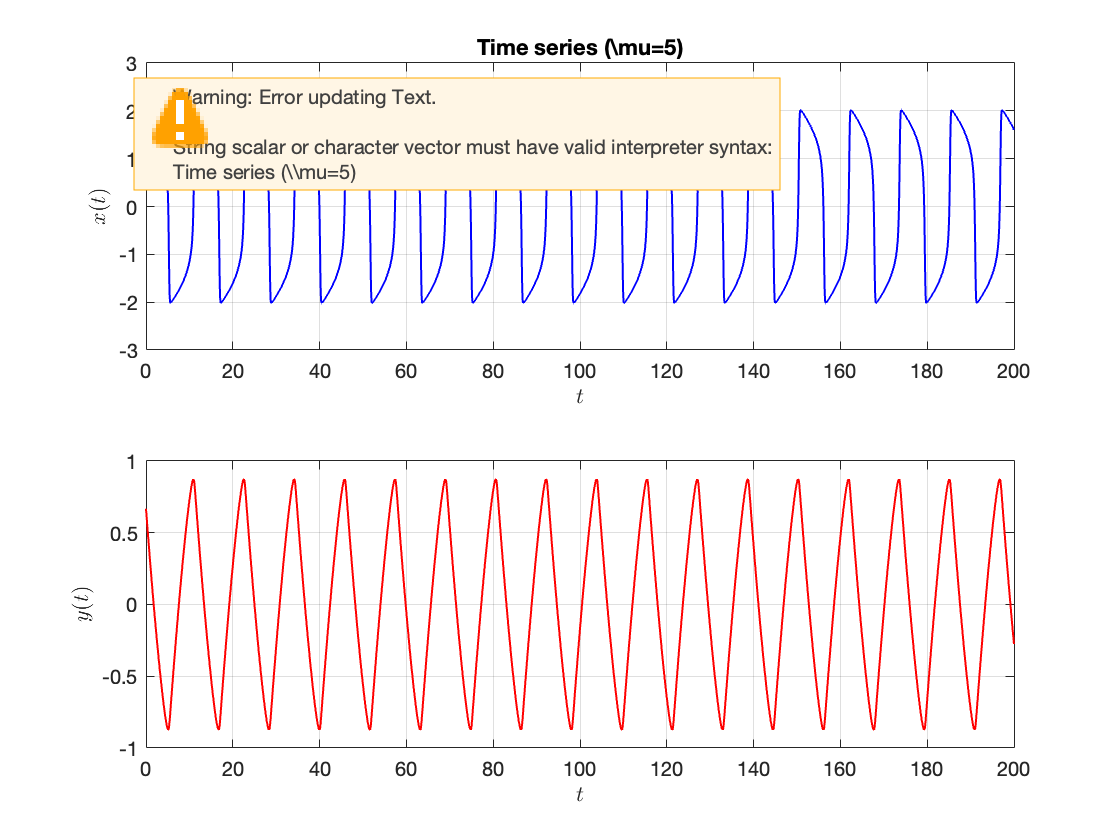

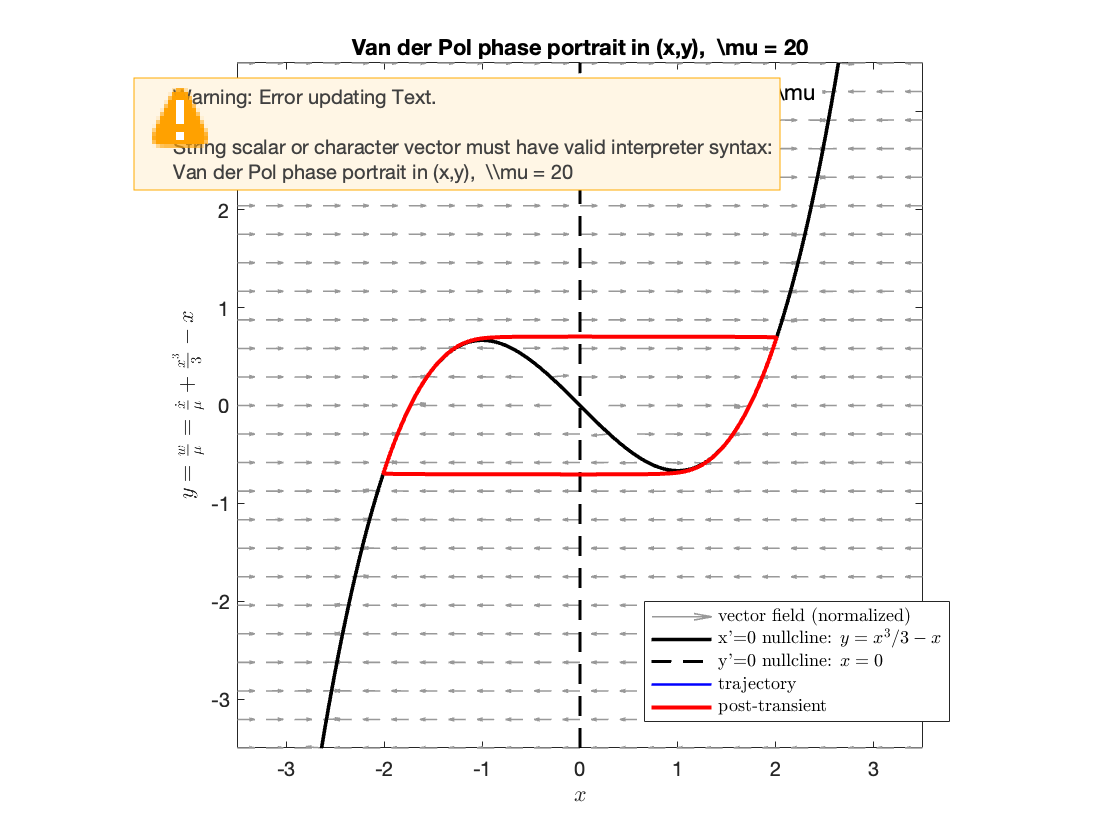

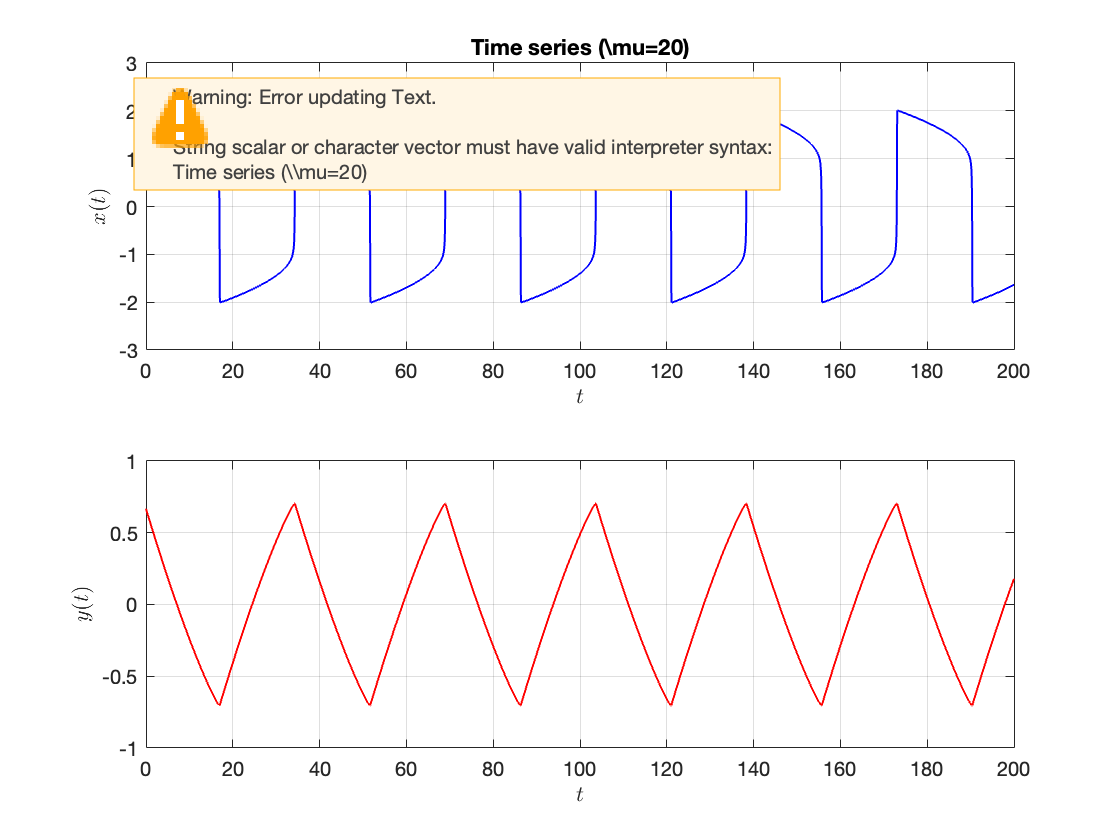

% ex2_van_der_pol_limitcycle.m
% Van der Pol oscillator in a transformed (x,y) phase plane
%
% Goal (recitation demo):
%   - Rewrite Van der Pol using the variable change suggested in class:
%       x'' + mu (x^2 - 1) x' + x = 0
%     Define
%       w := x' + mu (x^3/3 - x)    (a Liénard-type transform)
%     Then
%       w' = x'' + mu (x^2 - 1) x' = -x
%     and define the scaled variable
%       y := w/mu.
%
%   - This yields a 2D first-order system in the (x,y)-plane:
%       x' = mu*( y - (x^3/3 - x) ) = mu*(y + x - x^3/3)
%       y' = -(1/mu)*x
%
%   - We then visualize:
%       (i) nullclines in (x,y)
%       (ii) vector field
%       (iii) trajectories and the limit cycle (for mu>0)
%       (iv) OPTIONAL: estimate period/amplitude vs mu (no toolboxes required)
%
% Notes:
%   - Here y is NOT the velocity x' (it is a transformed variable).
%   - If you want to start from (x0, xdot0), convert to (x0, y0) via:
%         y0 = xdot0/mu + (x0^3/3 - x0)
%
% Author: (your name / course)
% -------------------------------------------------------------------------

clear; close all; clc;

%% --------------------------- Parameters ---------------------------------
mu_list = [0.1, 1, 5, 20];         % explore small -> moderate -> stiff regime
Tmax    = 200;                    % integrate long enough to converge to cycle
tspan   = [0, Tmax];

% initial conditions specified as (x0, xdot0) for convenience, then converted
x0    = 2.0;
xdot0 = 0.0;

% Vector-field plot window (x-y plane)
xlim_plot = [-3.5, 3.5];
ylim_plot = [-3.5, 3.5];

% Vector-field grid density (keep moderate to avoid clutter)
Nx = 25; Ny = 25;

%% ------------------------ Main loop over mu ------------------------------
% Store amplitude/period estimates (optional)
Amp_est = nan(size(mu_list));
Per_est = nan(size(mu_list));

for k = 1:numel(mu_list)
    mu = mu_list(k);

    % Convert (x0, xdot0) -> (x0, y0)
    y0 = xdot0/mu + (x0^3/3 - x0);
    z0 = [x0; y0];

    % Choose solver: for large mu, system becomes stiff (fast-slow)
    if mu >= 10
        solver = @ode15s;
        opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.2);
    else
        solver = @ode45;
        opts = odeset('RelTol',1e-9,'AbsTol',1e-11,'MaxStep',0.5);
    end

    % Integrate
    odefun = @(t,z) vdp_xy(t,z,mu);
    [t,z]  = solver(odefun, tspan, z0, opts);

    x = z(:,1);
    y = z(:,2);

    %% ---------------------- Phase plane figure ---------------------------
    figure('Name',sprintf('Van der Pol in (x,y), mu=%.3g',mu),'Color','w');
    hold on; box on;

    % (A) Vector field
    [X,Y] = meshgrid(linspace(xlim_plot(1),xlim_plot(2),Nx), ...
                     linspace(ylim_plot(1),ylim_plot(2),Ny));
    U = mu*(Y + X - (X.^3)/3);   % x' component
    V = -(1/mu)*X;               % y' component

    % Normalize arrows to avoid huge arrows for large mu
    S = sqrt(U.^2 + V.^2) + 1e-12;
    Uq = U ./ S;
    Vq = V ./ S;

    quiver(X,Y,Uq,Vq,0.45,'LineWidth',0.8,'Color',[0.6 0.6 0.6]);

    % (B) Nullclines
    % x'-nullcline: x'=0  => y = x^3/3 - x (cubic)
    xx = linspace(xlim_plot(1),xlim_plot(2),800);
    y_xnull = (xx.^3)/3 - xx;
    plot(xx, y_xnull, 'k-', 'LineWidth', 1.8);

    % y'-nullcline: y'=0  => x = 0
    plot([0 0], ylim_plot, 'k--', 'LineWidth', 1.6);

    % (C) Trajectory (whole)
    plot(x, y, 'b-', 'LineWidth', 1.2);

    % Highlight "near-limit-cycle" segment by discarding transient
    % (heuristic: keep last 25% of samples)
    idx0 = round(0.75*numel(t));
    plot(x(idx0:end), y(idx0:end), 'r-', 'LineWidth', 2.0);

    xlabel('$x$','Interpreter','latex');
    ylabel('$y=\frac{w}{\mu}=\frac{\dot{x}}{\mu}+\frac{x^3}{3}-x$','Interpreter','latex');
    title(sprintf('Van der Pol phase portrait in (x,y),  \\mu = %.3g',mu), ...
        'Interpreter','latex');

    legend({'vector field (normalized)','x''=0 nullcline: $y=x^3/3-x$', ...
            'y''=0 nullcline: $x=0$','trajectory','post-transient'}, ...
            'Interpreter','latex','Location','best');

    axis([xlim_plot ylim_plot]);
    axis square;

    % Annotate the fast-slow geometry when mu is large
    if mu >= 10
        text(xlim_plot(1)+0.1, ylim_plot(2)-0.3, ...
            sprintf('Large \\mu: fast-slow\\nfast: x''=\\mu(\\cdot), slow: y''=-x/\\mu'), ...
            'Interpreter','latex','FontSize',11,'BackgroundColor','w');
    end

    %% ---------------------- Time series figure ---------------------------
    figure('Name',sprintf('Time series, mu=%.3g',mu),'Color','w');
    subplot(2,1,1);
    plot(t,x,'b-','LineWidth',1.0); grid on;
    xlabel('$t$','Interpreter','latex'); ylabel('$x(t)$','Interpreter','latex');
    title(sprintf('Time series (\\mu=%.3g)',mu),'Interpreter','latex');

    subplot(2,1,2);
    plot(t,y,'r-','LineWidth',1.0); grid on;
    xlabel('$t$','Interpreter','latex'); ylabel('$y(t)$','Interpreter','latex');

    %% -------- Optional: estimate amplitude & period from x(t) ------------
    % Use only the tail to reduce transient effects.
    t_tail = t(idx0:end);
    x_tail = x(idx0:end);
    y_tail = y(idx0:end);

    [tpeaks, xpeaks] = local_peak_times(t_tail, x_tail);

    if numel(tpeaks) >= 3
        % Period estimate: average spacing of last few peak times
        % (avoid first peak in tail; use last up to 6 intervals)
        dt = diff(tpeaks);
        m  = min(numel(dt), 6);
        Per_est(k) = mean(dt(end-m+1:end));

        % Amplitude estimate: half peak-to-trough range on tail
        Amp_est(k) = 0.5*(max(y_tail) - min(y_tail));
    else
        % Fallback
        Per_est(k) = nan;
        Amp_est(k) = 0.5*(max(y_tail) - min(y_tail));
    end

end

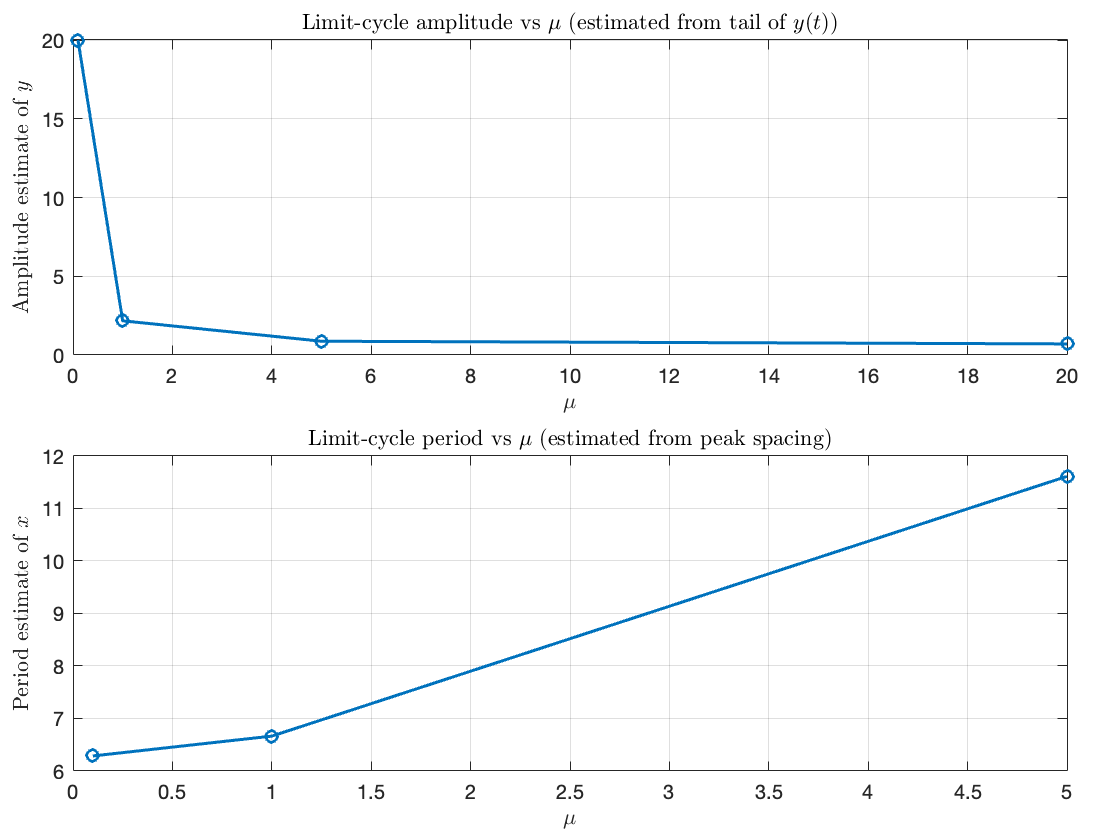


%% ---------------- Plot amplitude & period vs mu (optional summary) -------
figure('Name','Van der Pol: amplitude & period vs mu','Color','w');
tiledlayout(2,1,'Padding','compact','TileSpacing','compact');

nexttile;
plot(mu_list, Amp_est, 'o-','LineWidth',1.5); grid on;
xlabel('$\mu$','Interpreter','latex');
ylabel('Amplitude estimate of $y$','Interpreter','latex');
title('Limit-cycle amplitude vs $\mu$ (estimated from tail of $y(t)$)','Interpreter','latex');

nexttile;
plot(mu_list, Per_est, 'o-','LineWidth',1.5); grid on;
xlabel('$\mu$','Interpreter','latex');
ylabel('Period estimate of $x$','Interpreter','latex');
title('Limit-cycle period vs $\mu$ (estimated from peak spacing)','Interpreter','latex');


%% ---------------------------- Functions ---------------------------------

function dz = vdp_xy(~, z, mu)
    % Van der Pol in transformed coordinates (x,y):
    %   x' = mu*(y + x - x^3/3)
    %   y' = -(1/mu)*x
    x = z(1);
    y = z(2);
    dx = mu*(y + x - x^3/3);
    dy = -(1/mu)*x;
    dz = [dx; dy];
end

function [tpeaks, xpeaks] = local_peak_times(t, x)
    % Simple peak finder (no toolboxes).
    % Returns times/values of local maxima in x(t).
    %
    % Criteria: x(i-1) < x(i) > x(i+1) with a mild amplitude threshold.
    n = numel(x);
    if n < 3
        tpeaks = [];
        xpeaks = [];
        return;
    end

    % Threshold to avoid tiny numerical wiggles
    thr = 1e-6 * max(1, max(abs(x)));

    idx = [];
    for i = 2:n-1
        if (x(i) - x(i-1) > 0) && (x(i) - x(i+1) > 0) && (abs(x(i)) > thr)
            idx(end+1) = i; %#ok<AGROW>
        end
    end

    tpeaks = t(idx);
    xpeaks = x(idx);

    % Optional: enforce minimum separation (avoid double-counting due to noise)
    if numel(tpeaks) >= 2
        minSep = 0.2; % crude; adjust if needed
        keep = true(size(tpeaks));
        last = tpeaks(1);
        for j = 2:numel(tpeaks)
            if tpeaks(j) - last < minSep
                keep(j) = false;
            else
                last = tpeaks(j);
            end
        end
        tpeaks = tpeaks(keep);
        xpeaks = xpeaks(keep);
    end
end